x=0; % initial cordiantes of center
y=0; % initial cordiantes of center
r=0.1; % radius in m 
sample= 8 ; % how many samples are used to create this circle
sample_1 = sample - 1;
th = 0:(pi*2)/sample_1:2*pi; % full circle in rads devided into sample 
xunit = r * cos(th) + x;
yunit = r * sin(th) + y;
x_ = xunit;
y_ = yunit;
[m,n] = size(xunit);
sample_ = n;
z_ = zeros(1,sample_); % create array of zeroes for z since we are in 3d space
cir = [x_;y_;z_];
cir_ = cir'; % transpose of matrix , we are using this format , colums are x,y,z 

## Code to rotate our trajectory and move it in x,y,z direction ( be careful about order)

points_ represents our dot map 

% rotate created circle
% rpy2r(around x, around y , around z);
xrot = 0; %70
yrot = 30; %30
zrot = 35; %35
%% Move all points by x,y,z 
xmove = 0.25;
ymove = 0;
zmove = 0.4;

T=rpy2r(xrot,yrot,zrot,'deg'); %%Create rotation matrix 
for i=1:sample_ 
    points_(i,:)=cir_(i,:)*T; %% rotate every dot by that rotation matrix
end
points_;  % print rotated trajectory
% points_  represent our object
% move created circle in x directions
for i=1:sample_
    cir3(i,1)= points_(i,1)+xmove;
    points_(i,1) = cir3(i,1);
end
 points_;
 % move created circle in y directions
for i=1:sample_
    cir3(i,2)= points_(i,2)+ymove;
    points_(i,2) = cir3(i,2);
end
 points_;
 % move created circle in z directions 
for i=1:sample_
    cir3(i,3)= points_(i,3)+zmove;
    points_(i,3) = cir3(i,3);
end
 points_;


**Creates trajectory for our robot **

in mstraj function we set:

traj = mstraj(p, qdmax, tseg, q0, dt, tacc, options)

- p points we are runing thru , in our case points_

- qdmax (1×N) are axis speed limits which cannot be exceeded ( in m/s)

- tseg (1×M) are the durations for each of the K segments( in our case [])

- q0 (1×N) are the initial axis coordinates , in our case start

- dt is the time step

-  tacc (1×1) is the acceleration time used for all segment transitions 

-  tacc (1×M) is the acceleration time per segment, tacc(i) is the acceleration time for the transition from segment i to segment i+1. tacc(1) is also the acceleration time at the start of segment 1.

The number of steps in the trajectory m is a function of the number of via points and the time or velocity limits that apply.

%% start of our trajectory, first point of points_
start = points_(1,:);
time_step = 0.02;
%%via = [0.15 0 0 ; start];
x = mstraj(points_,[0.07 0.07 0.07],[],start,time_step,0,'verbose');

------------------- segment 1
seg 1, slowest axis 1, time required 0
------------------- segment 2
seg 2, slowest axis 2, time required 1.24
------------------- segment 3
seg 3, slowest axis 2, time required 0.92
------------------- segment 4
seg 4, slowest axis 1, time required 1.08
------------------- segment 5
seg 5, slowest axis 2, time required 1.02
------------------- segment 6
seg 6, slowest axis 2, time required 1.2
------------------- segment 7
seg 7, slowest axis 1, time required 1
------------------- segment 8
seg 8, slowest axis 1, time required 0.94


[m,n] = size(x)

m = 370

n = 3

As we can see we have "m" points in our movement 

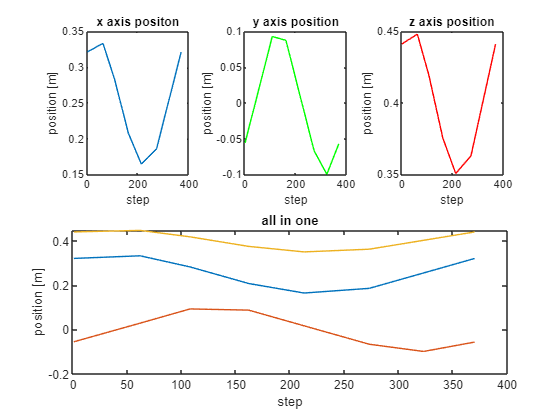

HG_matrix = zeros(4,4,m);
J_angles = zeros(m,6);
J_speed = zeros(m,6);

for i = 1:m
    for j = 1:3
    if x(i,j) < 1e-7 && x(i,j) > -1e-7
       x(i,j) = 0;
    end
    end
end
figure (1)
subplot(2,3,1) % used to create multiple plots side by side
plot(x(:,1))
title('x axis positon')
xlabel('step')
ylabel('position [m]')

subplot(2,3,2)
plot(x(:,2),'color','g')
title('y axis position')
xlabel('step')
ylabel('position [m]')

subplot(2,3,3)
plot(x(:,3),'color','r')
title('z axis position')
xlabel('step')
ylabel('position [m]')

subplot(2,3,[4,6])
plot(x)
title('all in one')
xlabel('step')
ylabel('position [m]')

total duration of robot trajectory in seconds

total_time = time_step * m

total_time = 7.4000

## speed in x,y,z direction

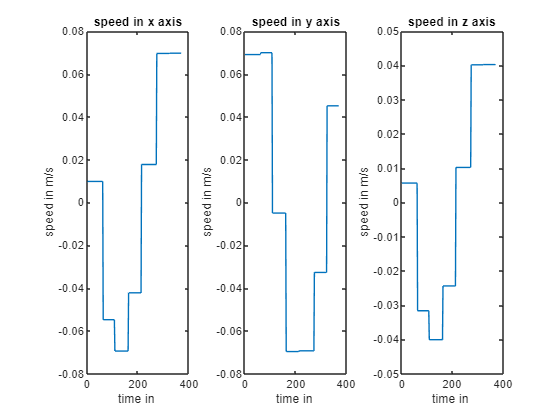

% real speeds are these values / time_step
x_dot = gradient(x(:,1)/time_step);
y_dot = gradient(x(:,2)/time_step);
z_dot = gradient(x(:,3)/time_step);
 % clear previous subplots

figure(2)
clf
subplot(1,3,1)
plot(x_dot)
title('speed in x axis')
xlabel('time in ')
ylabel('speed in m/s')

subplot(1,3,2)
plot(y_dot)
title('speed in y axis')
xlabel('time in ')
ylabel('speed in m/s')

subplot(1,3,3)
plot(z_dot)
title('speed in z axis')
xlabel('time in ')
ylabel('speed in m/s')


% acceleration in x,y,z direction
% real accelerations are these values / time_step

%%acceleration = x_dot./time_step;
%x_dot21 = gradient(x_dot);
x_dot2 = gradient(x_dot);
y_dot2 = gradient(y_dot);
z_dot2 = gradient(z_dot);

